Q4

First import image into the file

clc;clear workspace;
edges=imread("edges.tif");
wheel=imread("wheel.tif");
edges=im2gray(edges);
wheel=im2gray(wheel);
edges=double(edges);
wheel=double(wheel);
[m,n]=size(edges);


Use fft2 and fftshift to apply 2D Fourier transform of both image and shift the low frequency component to the center of the image

edges_freq=fftshift(fft2(edges));
wheel_freq=fftshift(fft2(wheel));

Creat the ideal low pass filter (ILPF) and Gaussian low pass filter (Gau), the mean of the gaussian distributation is mu=0 and variance sigma=1/4 of the maxmam frequency and the radius of the ILPF equals to half of the maximun frequency. In this case, the maximum frequency appears at 128 pixles away from the center of the image. So, variance of Gau is 32 and radius of ILPF is 64.

ILPF=zeros(m,n);
Gau=zeros(m,n);
r=(m+n)/8;
sigma=(m+n)/16;
mu=0;

for i=1:m
    for j=1:n
        if ((m/2-i)^2+(n/2-j)^2) < r^2
        ILPF(i,j)=1;

        end
        x=sqrt((m/2-i)^2+(n/2-j)^2);
        Gau(i,j)=(1 / (sigma * sqrt(2 * pi))) * exp(-((x - mu).^2) / (2 * sigma^2));

    end
end

Apply above filter to the image using multiplication in frequency domain.

edges_freq_ILPF=edges_freq.*ILPF;
edges_freq_Gau=edges_freq.*Gau;
wheel_freq_ILPF=wheel_freq.*ILPF;
wheel_freq_Gau=wheel_freq.*Gau;

Using ifftshift to shift low frequency component back to the corner and inverse fft to get image in the Cartesian domain. 

edges_ILPF=ifft2(ifftshift(edges_freq_ILPF));
edges_Gau=ifft2(ifftshift(edges_freq_Gau));
wheel_ILPF=ifft2(ifftshift(wheel_freq_ILPF));
wheel_Gau=ifft2(ifftshift(wheel_freq_Gau));

Plot image, all complex number image are plotted using magnitude. The image of frequency domain are plotted using log scale for better visulization.

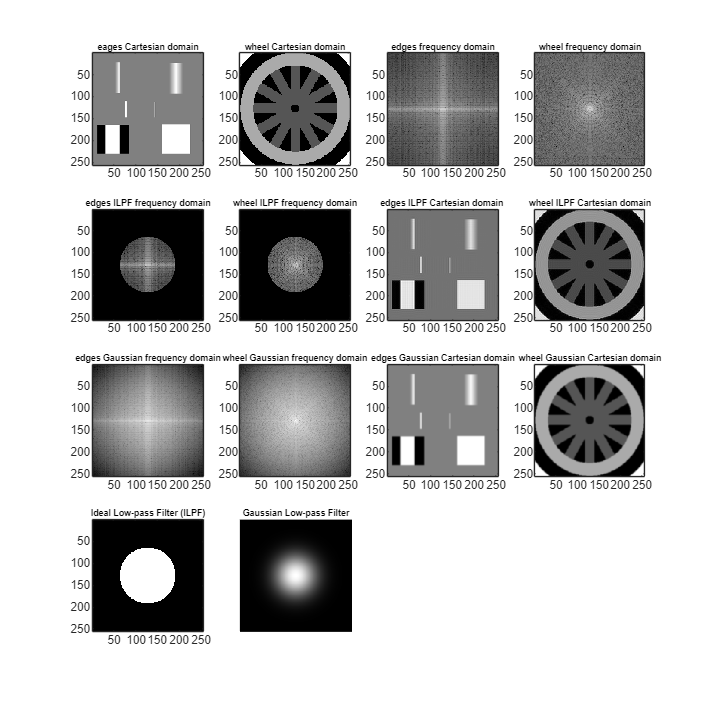

subplot(4,4,1)
imagesc(edges)
title('eages Cartesian domain','FontSize',6)
colormap('gray')
warning('off', 'all');
subplot(4,4,2)
imagesc(wheel)
title('wheel Cartesian domain','FontSize',6)
colormap('gray')
subplot(4,4,3)
imagesc(log(abs(edges_freq)))
title('edges frequency domain','FontSize',6)
colormap('gray')
subplot(4,4,4)
imagesc(log(abs(wheel_freq)))
title('wheel frequency domain','FontSize',6)
colormap('gray')
subplot(4,4,5)
imagesc(log(abs(edges_freq_ILPF)))
title('edges ILPF frequency domain','FontSize',6)
colormap('gray')
subplot(4,4,6)
imagesc(log(abs(wheel_freq_ILPF)))
title('wheel ILPF frequency domain','FontSize',6)
colormap('gray')
subplot(4,4,7)
imagesc(abs(edges_ILPF))
title('edges ILPF Cartesian domain ','FontSize',6)
colormap('gray')
subplot(4,4,8)
imagesc(abs(wheel_ILPF))
title('wheel ILPF Cartesian domain','FontSize',6)
colormap('gray')
subplot(4,4,9)
imagesc(log(abs(edges_freq_Gau)))
title('edges Gaussian frequency domain','FontSize',6)
colormap('gray')
subplot(4,4,10)
imagesc(log(abs(wheel_freq_Gau)))
title('wheel Gaussian frequency domain','FontSize',6)
colormap('gray')
subplot(4,4,11)
imagesc(abs(edges_Gau))
title('edges Gaussian Cartesian domain','FontSize',6)
colormap('gray')
subplot(4,4,12)
imagesc(abs(wheel_Gau))
title('wheel Gaussian Cartesian domain','FontSize',6)
colormap('gray')
subplot(4,4,13)
imagesc(ILPF)
title('Ideal Low-pass Filter (ILPF)','FontSize',6)
colormap('gray')
subplot(4,4,14)
imagesc(Gau)
title('Gaussian Low-pass Filter','FontSize',6)
colormap('gray')
axis image off;
truesize;

Clearly, the ideal low pass filter gives the image ringing artifact after filtering because the inverse FFT of the filter it self is a sinc function. Gaussian low pass filter does not have this kind of artifact. Both of the filters are smoothing the edge of the image. If take a close look at the edge, the result of Gaussian filter is more smooth.

In general, the gaussian filter is better for processing image in the frequency domain.